# Bessel filter (1-5 order)

***Collated and calculated by Zhou Yiliang (zhouyiliang0311@163.com) , 2023.2***

The filter implementation is base on the source on Wikipedia and python library scipy.signal.bessel.

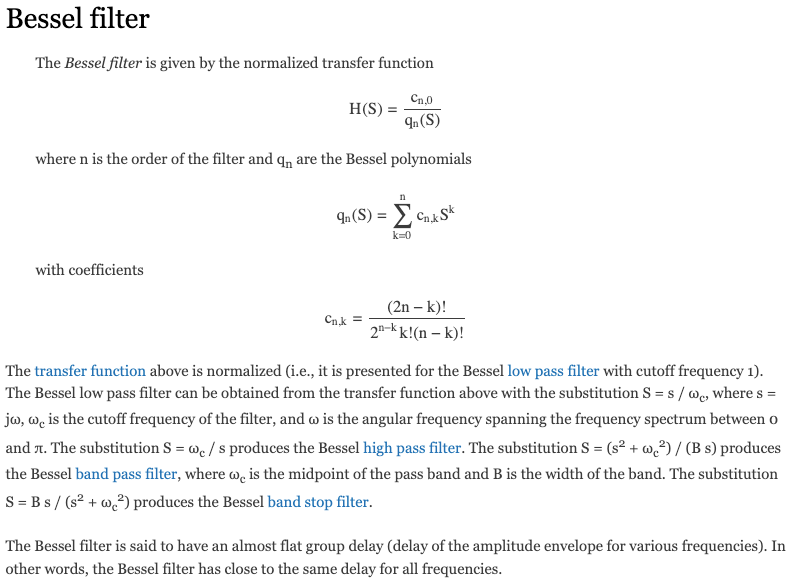

[https://www.recordingblogs.com/wiki/bessel-filter](https://www.recordingblogs.com/wiki/bessel-filter)

[https://en.wikipedia.org/wiki/Bessel_filter](https://en.wikipedia.org/wiki/Bessel_filter)

[https://docs.scipy.org/doc/scipy/reference/generated/scipy.signal.bessel.html](https://docs.scipy.org/doc/scipy/reference/generated/scipy.signal.bessel.html)

## 1 st order


$$H\left(s\right)=\;$$

$$\frac{1}{1+s\;}$$
     

Low:$s=\frac{s}{w_c }$       High:  $s=\frac{w_c }{s}$

lowpass:$H\left(s\right)=\;$$\frac{1}{1+\frac{s}{w_c }\;}$ 

Highpass: $H\left(s\right)=\;$$\frac{1}{1+\frac{w_c }{s}\;\;}$

Cutoff frequency $w_c =2\;\pi \;f_c /f_s$. 

Applying the [bilinear transformation](https://www.recordingblogs.com/wiki/bilinear-transformation): s=2*(z−1)/(z+1), the transfer function in the z-domain can be expressed as:

lowpass:


$$H\left(z\right)=\;$$

$$\frac{{w_c \;+w_c z}^{-1} }{\left({\;w}_c +2\right)+\left(w_{c\;} -2\right)z^{-1} }$$


Highpass


$$H\left(z\right)=\;$$

$$\frac{{2-2z}^{-1} }{\left({\;w}_c +2\right)+\left(w_{c\;} -2\right)z^{-1} }$$


The `b` and `a` coefficients can be obtained by comparing the numerator and denominator of the transfer function to the standard form of a digital filter:

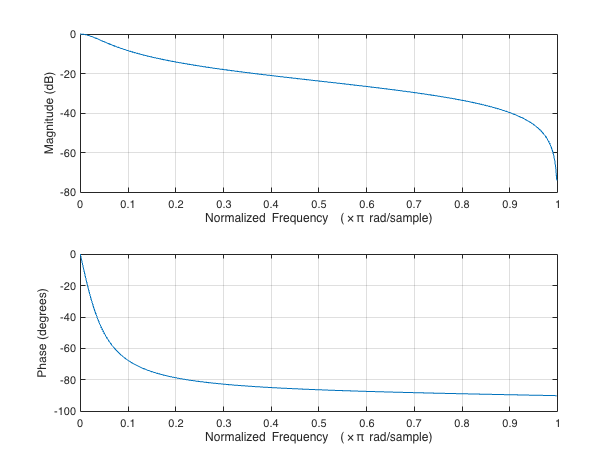

clear;clc;
fs = 48e3;
fc = 1000; %cutoff frequency
w_c = 2*pi*fc/fs; %normalized cutoff frequency of the filte
b_l1 = [w_c w_c];
a_l1 = [w_c+2 w_c-2];
% freqz(b_d, a_d)
freqz(b_l1, a_l1);

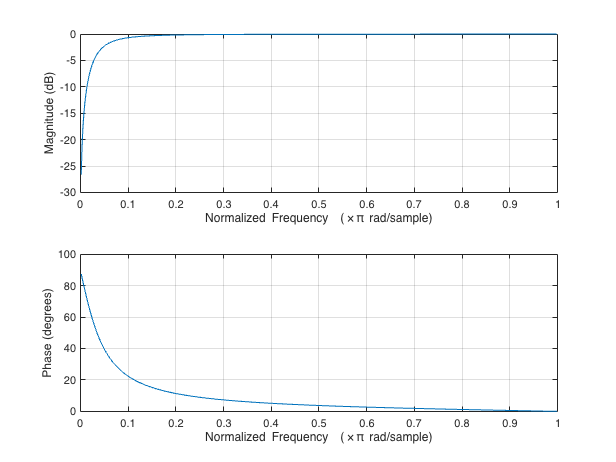

[H_low_1, w] = freqz(b_l1,a_l1);
b_h1 = [2 -2];
a_h1 = [w_c+2 w_c-2];
freqz(b_h1, a_h1);

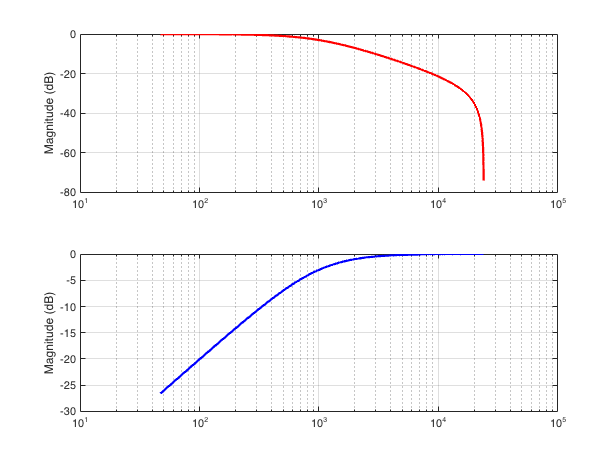

[H_high_1, w] = freqz(b_h1,a_h1);
figure
subplot(2,1,1)
semilogx(w/pi*fs/2, 20*log10(abs(H_low_1)), '-r', 'LineWidth', 2);
ylabel('Magnitude (dB)');
grid on;
subplot(2,1,2)
semilogx(w/pi*fs/2, 20*log10(abs(H_high_1)), '-b', 'LineWidth', 2);
ylabel('Magnitude (dB)');
grid on;

## 2 st order


$$H\left(s\right)=\;$$

$$\frac{3}{s^2 +3s+3}$$
     

Low:$s=\frac{s}{w_c }$       High:  $s=\frac{w_c }{s}$

lowpass:$H\left(s\right)=\;$$\frac{3}{\left({\left.\frac{s}{w_c }\right)}^2 +3\frac{s}{w_c }+3\right.}$ 

Highpass: $H\left(s\right)=\;$$\frac{3}{\left({\left.\frac{w_c }{s}\right)}^2 +3\frac{w_c }{s}+3\right.}$

Cutoff frequency $w_c =2\;\pi \;f_c /f_s$. 

Applying the [bilinear transformation](https://www.recordingblogs.com/wiki/bilinear-transformation): s=2*(z−1)/(z+1), the transfer function in the z-domain can be expressed as:

lowpass:


$$H\left(z\right)=\;$$

$$\frac{{3w_c^2 \left(1+2z^{-1} +z^{-2} \right)\;} }{\left({\;w}_c +2\right)+\left(w_{c\;} -2\right)z^{-1} }$$


Highpass


$$H\left(z\right)=\;$$

$$\frac{{12-24z}^{-1} +12z^{-2} }{\left({\;w}_c^2 +6w_c +12\right)+\left({2w}_{c\;}^2 -24\right)z^{-1} +\left({\;w}_c^2 -6w_c +12\right)z^{-2} }$$


The `b` and `a` coefficients can be obtained by comparing the numerator and denominator of the transfer function to the standard form of a digital filter:

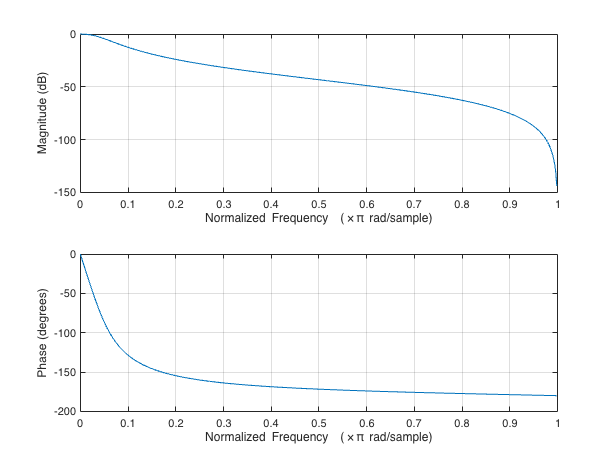

% fs = 48e3;
fc_l2 = fc/1.361654129; %3dB frequency normalization constant
w_c = 2*pi*fc_l2/fs; %normalized cutoff frequency of the filte
b_l2 = 3 * w_c^2 * [1, 2, 1];
a_l2 = [4+6*w_c+3*w_c^2, 6*w_c^2-8, 4-6*w_c+3*w_c^2];
% freqz(b_d, a_d)
freqz(b_l2, a_l2);

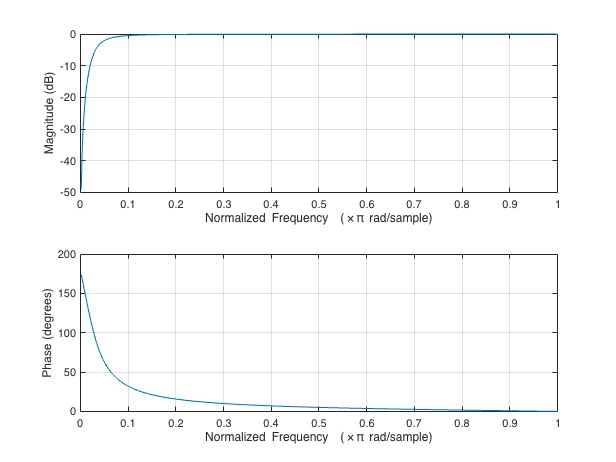

[H_low_2, w] = freqz(b_l2,a_l2);
fc_h2 = fc*1.361654129; %3dB frequency normalization constant
w_c = 2*pi*fc_h2/fs; %normalized cutoff frequency of the filte
b_h2 = [12, -24, 12];
a_h2 = [w_c^2+6*w_c+12, 2*w_c^2-24, w_c^2-6*w_c+12];
freqz(b_h2, a_h2);

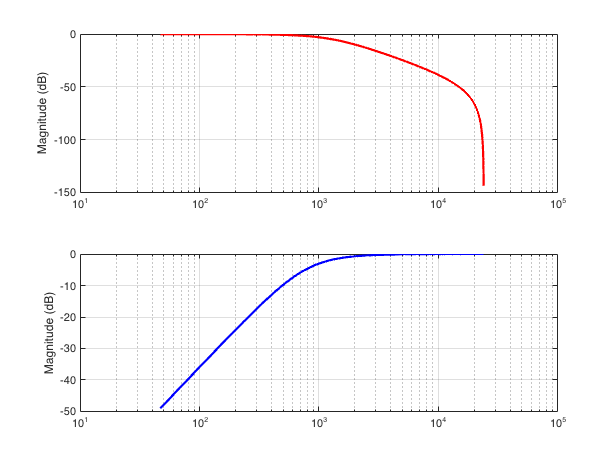

[H_high_2, w] = freqz(b_h2,a_h2);
figure
subplot(2,1,1)
semilogx(w/pi*fs/2, 20*log10(abs(H_low_2)), '-r', 'LineWidth', 2);
ylabel('Magnitude (dB)');
grid on;
subplot(2,1,2)
semilogx(w/pi*fs/2, 20*log10(abs(H_high_2)), '-b', 'LineWidth', 2);
ylabel('Magnitude (dB)');
grid on;

## 3 rd order

lowpass:


$$H\left(s\right)=\;$$

$$\frac{15w_c^3 \;}{s^3 +6w_c \;s^2 +15w_c^2 \;s+15w_c^3 }$$
             
$$H\left(s\right)=\;$$

$$\frac{15w_c^3 \;s^{-3} }{1+6w_c s^{-1} +15w_c^2 \;s\;}$$
 

Cutoff frequency $w_c =2\;\pi \;f_c /f_s$. 

First, we can simplify the denominator:

s^3 + 6 * w_c * s^2 + 15 * w_c^2 * s + 15 * w_c^3 = (2 * (z - 1)/(z + 1))^3 + 6 * w_c * (2 * (z - 1)/(z + 1))^2 + 15 * w_c^2 * (2 * (z - 1)/(z + 1)) + 15 * w_c^3

Applying the [bilinear transformation](https://www.recordingblogs.com/wiki/bilinear-transformation): s=2*(z−1)/(z+1), the transfer function in the z-domain can be expressed as:

Highpass:

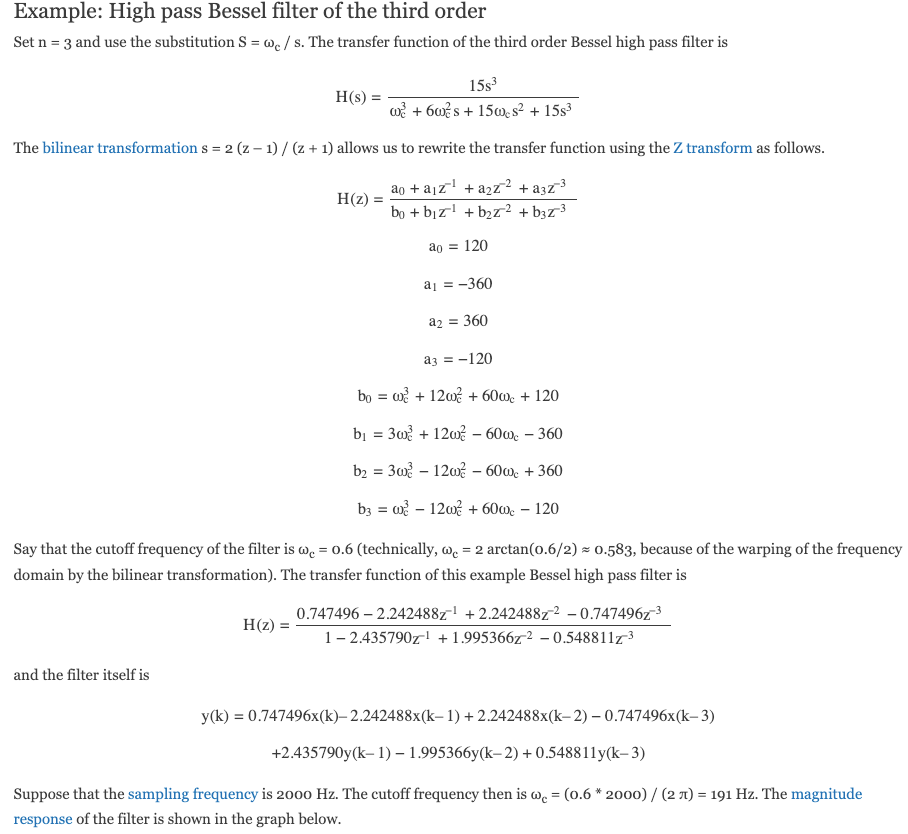

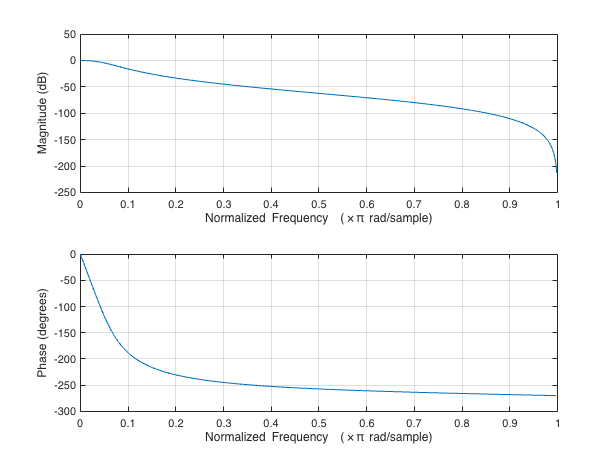

% fs = 48e3;
fc_l3 = fc/1.755672389; %3dB frequency normalization constant
w_c = 2*pi*fc_l3/fs; %normalized cutoff frequency of the filter
b_l3 = 15*w_c^3*[1, 3, 3, 1];
a_l3 = [(8 + 24*w_c + 30*w_c^2+15*w_c^3), (-24 - 24*w_c + 30*w_c^2 + 45*w_c^3),(24 - 24*w_c - 30*w_c^2 + 45*w_c^3), (-8 + 24*w_c - 30*w_c^2 + 15*w_c^3)];
freqz(b_l3, a_l3)

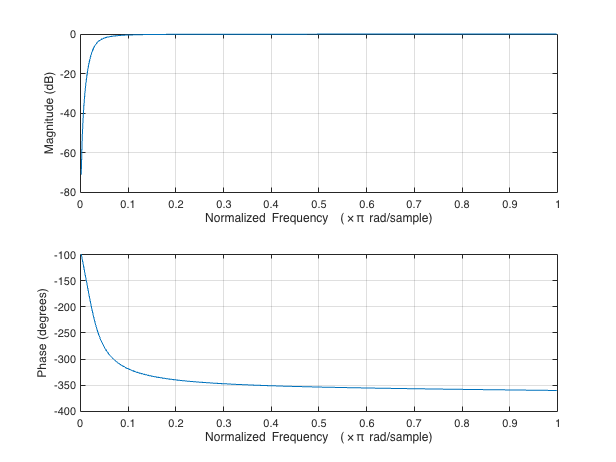

[H_low_3, w] = freqz(b_l3,a_l3);
fc_h3 = fc*1.755672389; %3dB frequency normalization constant
w_c = 2*pi*fc_h3/fs; %normalized cutoff frequency of the filter
b_h3 = [120 -360 360 -120];
a0=w_c^3+12 * w_c^2+60*w_c+120;
a1= 3*w_c^3 + 12*w_c^2 - 60*w_c - 360;
a2= 3*w_c^3 - 12*w_c^2 - 60*w_c + 360;
a3= w_c^3 - 12*w_c^2 + 60*w_c - 120;
a_h3 = [a0 a1 a2 a3];
% [b_d, a_d] = bilinear(b, a, fs);
% freqz(b_d, a_d)
freqz(b_h3, a_h3)

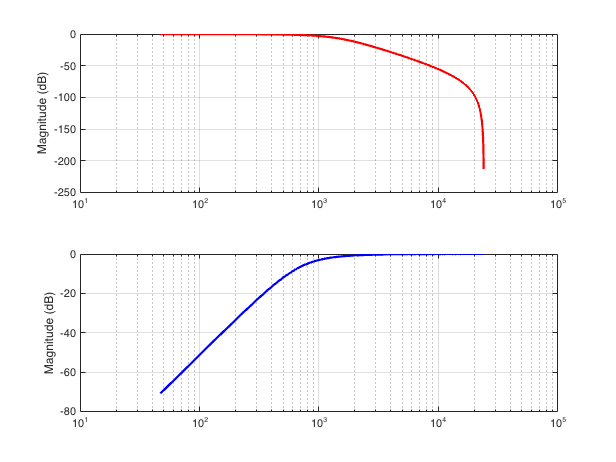

[H_high_3, w] = freqz(b_h3,a_h3);
figure
subplot(2,1,1)
semilogx(w/pi*fs/2, 20*log10(abs(H_low_3)), '-r', 'LineWidth', 2);
ylabel('Magnitude (dB)');
grid on;
subplot(2,1,2)
semilogx(w/pi*fs/2, 20*log10(abs(H_high_3)), '-b', 'LineWidth', 2);
ylabel('Magnitude (dB)');
grid on;

## 4 th order

Low:$s=\frac{s}{w_c }$       High:  $s=\frac{w_c }{s}$

Applying the [bilinear transformation](https://www.recordingblogs.com/wiki/bilinear-transformation) s=2*(z−1)/(z+1)

lowpass: $H\left(s\right)=\frac{105w_c^4 }{s^{4\;} +10s^3 w_c +45s^2 w_c^2 +105sw_c^3 +105w_c^4 }$


$$H\left(s\right)=\frac{105w_c^4 {\left(z+1\right)}^4 }{a_{0\;} +a_1 z^{-1} +a_2 z^{-2} +a_3 z^{-3} +a_4 z^{-4} }$$


highpass: $H\left(s\right)=\frac{105s^4 }{{w_c }^{4\;} +10{w_c }^3 s+45{w_c }^2 s^2 +105w_c s^3 +105s^4 }$

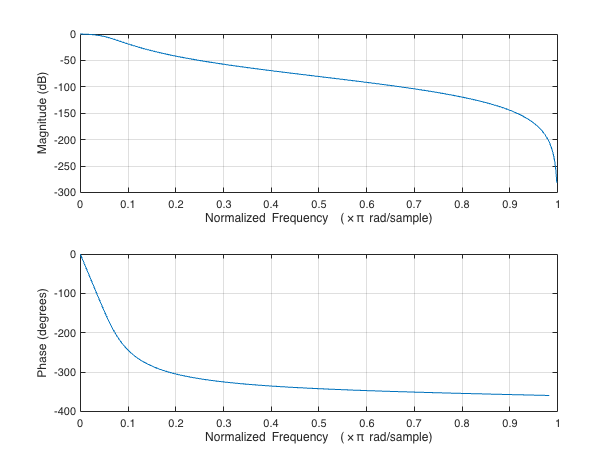

% fs = 48e3;
fc_l4 = fc/2.113917675; %3dB frequency normalization constant
w_c = 2*pi*fc_l4/fs; %normalized cutoff frequency of the filter
b_l4 = 105*w_c^4*[1 4 6 4 1];
a0= 105*w_c^4 +210*w_c^3 + 180*w_c^2 + 80*w_c + 16; %z^4 
a1= 420*w_c^4 + 420*w_c^3 + 0*w_c^2 - 160*w_c -64; %z^3 
a2= 630*w_c^4 + 0*w_c^3 + (-360)*w_c^2 + 0*w_c + 96; %z^2 
a3= 420*w_c^4 - 420*w_c^3 + 0*w_c^2 + 160*w_c - 64; %z^1 
a4= 105*w_c^4 - 210*w_c^3 + 180*w_c^2 - 80*w_c + 16; %z^0 
a_l4 = [a0 a1 a2 a3 a4];
freqz(b_l4, a_l4)

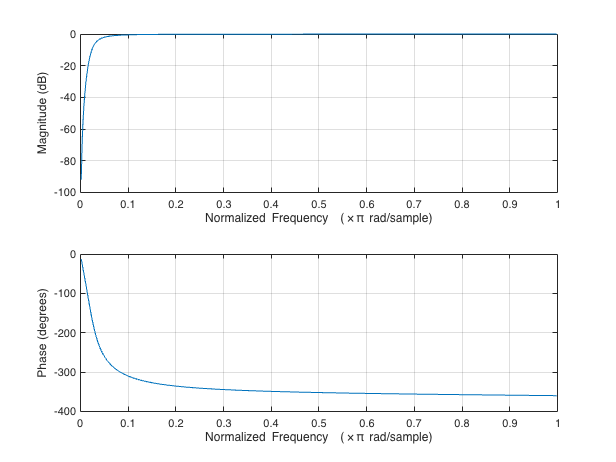

[H_low_4, w] = freqz(b_l4,a_l4);
fc_h4 = fc*2.113917675; %3dB frequency normalization constant
w_c = 2*pi*fc_h4/fs; %normalized cutoff frequency of the filter
b_h4 = 105*16*[1 -4 +6 -4 1];
a0= 1*w_c^4 +20*w_c^3 + 180*w_c^2 + 840*w_c + 1680; %z^4 
a1= 4*w_c^4 + 40*w_c^3 + 0*w_c^2 - 1680*w_c -6720; %z^3 
a2= 6*w_c^4 - 0*w_c^3 + (-360)*w_c^2 + 0*w_c + 10080; %z^2 
a3= 4*w_c^4 - 40*w_c^3 + 0*w_c^2 + 1680*w_c - 6720; %z^1 
a4= 1*w_c^4 - 20*w_c^3 + 180*w_c^2 - 840*w_c + 1680; %z^0 
a_h4 = [a0 a1 a2 a3 a4];
% [b_d, a_d] = bilinear(b, a, fs);
% freqz(b_d, a_d)
freqz(b_h4, a_h4)

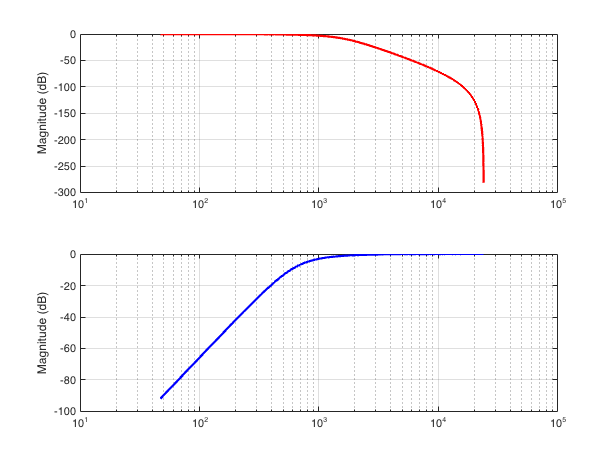

[H_high_4, w] = freqz(b_h4,a_h4);
figure
subplot(2,1,1)
semilogx(w/pi*fs/2, 20*log10(abs(H_low_4)), '-r', 'LineWidth', 2);
ylabel('Magnitude (dB)');
grid on;
subplot(2,1,2)
semilogx(w/pi*fs/2, 20*log10(abs(H_high_4)), '-b', 'LineWidth', 2);
ylabel('Magnitude (dB)');
grid on;

## 5 th order

Low:$s=\frac{s}{w_c }$       High:  $s=\frac{w_c }{s}$

Applying the [bilinear transformation](https://www.recordingblogs.com/wiki/bilinear-transformation) s=2*(z−1)/(z+1)

lowpass: $H\left(s\right)=\frac{945w_c^5 }{s^{5\;} +15s^4 w_c +105s^3 w_c^2 +420s^2 w_c^3 +945sw_c^4 +945w_c^5 }$


$$H\left(s\right)=\frac{945w_c^5 {\left(z+1\right)}^5 }{a_{0\;} +a_1 z^{-1} +a_2 z^{-2} +a_3 z^{-3} +a_4 z^{-4} +a_5 z^{-5} }$$


highpass: $H\left(s\right)=\frac{945s^5 }{w_c^5 +15w_c^4 s+105w_c^3 s^2 +420w_c^2 s^3 +945w_c s^4 +945s^5 }$

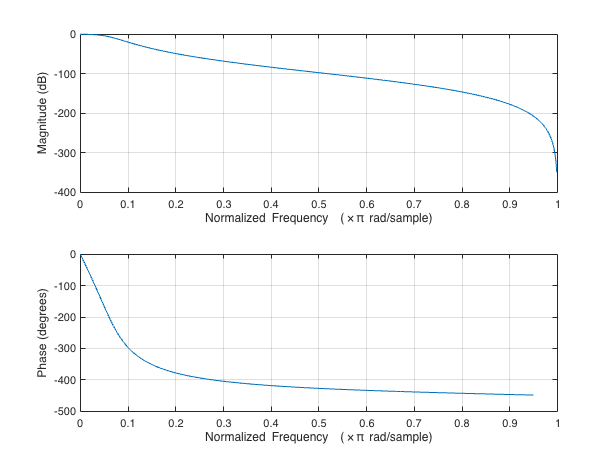

% fs = 48e3;
fc_l5 = fc/2.427410702; %3dB frequency normalization constant
w_c = 2*pi*fc_l5/fs; %normalized cutoff frequency of the filter
b_l5 = 945*w_c^5*[1 5 10 10 5 1];
a0= 945*w_c^5 + 1890*w_c^4 +1680*w_c^3 + 840*w_c^2 + 240*w_c + 32; %z^5 
a1= 4725*w_c^5 + 5760*w_c^4 +1680*w_c^3 + (-840)*w_c^2 + (-720)*w_c + (-160); %z^4 
a2= 9450*w_c^5 + 3780*w_c^4 +(-3360)*w_c^3 + (-1680)*w_c^2 + 480*w_c + 320; %z^3
a3= 9450*w_c^5 + (-3780)*w_c^4 +(-3360)*w_c^3 + 1680*w_c^2 + 480*w_c + (-320); %z^2 
a4= 4725*w_c^5 - 5670*w_c^4 +1680*w_c^3 + 840*w_c^2 + (-720)*w_c + 160; %z^1 
a5= 945*w_c^5 - 1890*w_c^4 +1680*w_c^3 - 840*w_c^2 + 240*w_c - 32; %z^0
a_l5 = [a0 a1 a2 a3 a4 a5];
freqz(b_l5, a_l5)

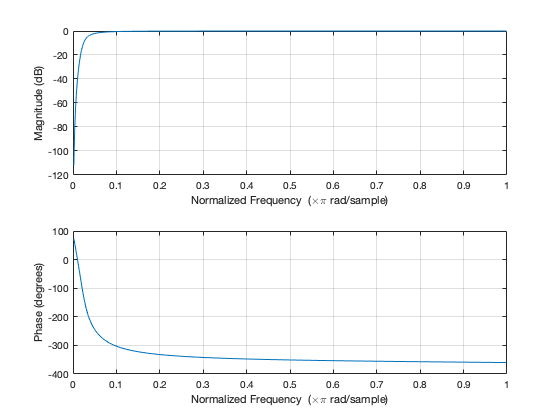

[H_low_5, w] = freqz(b_l5,a_l5);
fc_h5 = fc*2.427410702; %3dB frequency normalization constant
w_c = 2*pi*fc_h5/fs; %normalized cutoff frequency of the filter
b_h5 = 945*32*[1 -5 10 -10 5 -1];
a0= 1*w_c^5 + 30*w_c^4 +420*w_c^3 + 3360*w_c^2 + 15120*w_c + 30240; %z^5 
a1= 5*w_c^5 + 90*w_c^4 +420*w_c^3 + (-3360)*w_c^2 + (-45360)*w_c + (-151200); %z^4 
a2= 10*w_c^5 + 60*w_c^4 +(-840)*w_c^3 + (-6720)*w_c^2 + 30240*w_c + 302400; %z^3
a3= 10*w_c^5 + (-60)*w_c^4 +(-840)*w_c^3 + 6720*w_c^2 + 30240*w_c + (-302400); %z^2 
a4= 5*w_c^5 - 90*w_c^4 + 420*w_c^3 + 3360*w_c^2 + (-45360)*w_c + 151200; %z^1 
a5= 1*w_c^5 - 30*w_c^4 + 420*w_c^3 - 3360*w_c^2 + 15120*w_c - 30240; %z^0
a_h5 = [a0 a1 a2 a3 a4 a5];
% [b_d, a_d] = bilinear(b, a, fs);
% freqz(b_d, a_d)
freqz(b_h5, a_h5)

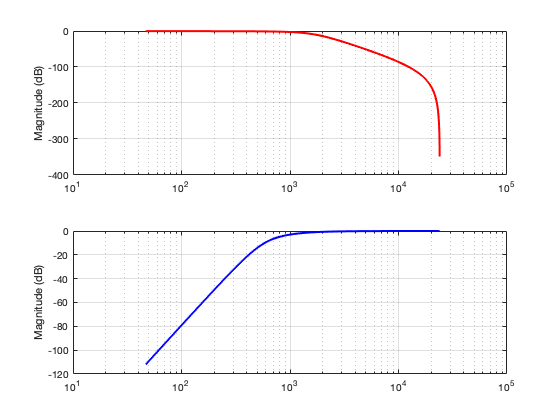

[H_high_5, w] = freqz(b_h5,a_h5);
figure
subplot(2,1,1)
semilogx(w/pi*fs/2, 20*log10(abs(H_low_5)), '-r', 'LineWidth', 2);
ylabel('Magnitude (dB)');
grid on;
subplot(2,1,2)
semilogx(w/pi*fs/2, 20*log10(abs(H_high_5)), '-b', 'LineWidth', 2);
ylabel('Magnitude (dB)');
grid on;

Plot together

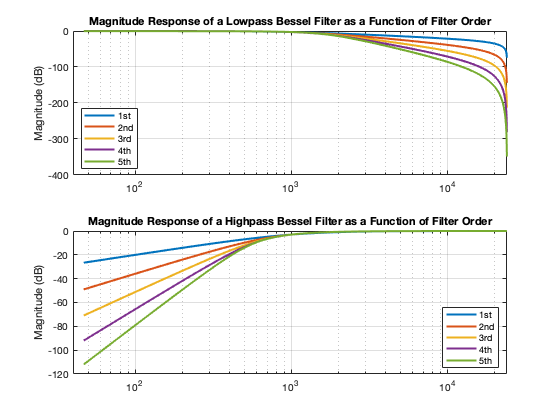

figure
subplot(2,1,1)
semilogx(w/pi*fs/2, 20*log10(abs(H_low_1)), 'LineWidth', 2);
hold on
semilogx(w/pi*fs/2, 20*log10(abs(H_low_2)), 'LineWidth', 2);
semilogx(w/pi*fs/2, 20*log10(abs(H_low_3)), 'LineWidth', 2);
semilogx(w/pi*fs/2, 20*log10(abs(H_low_4)), 'LineWidth', 2);
semilogx(w/pi*fs/2, 20*log10(abs(H_low_5)), 'LineWidth', 2);
legend({'1st', '2nd', '3rd', '4th', '5th'},'Location','southwest')
ylabel('Magnitude (dB)');
xlim([40 fs/2])
title('Magnitude Response of a Lowpass Bessel Filter as a Function of Filter Order')
grid on;
subplot(2,1,2)
semilogx(w/pi*fs/2, 20*log10(abs(H_high_1)), 'LineWidth', 2);
hold on
semilogx(w/pi*fs/2, 20*log10(abs(H_high_2)), 'LineWidth', 2);
semilogx(w/pi*fs/2, 20*log10(abs(H_high_3)), 'LineWidth', 2);
semilogx(w/pi*fs/2, 20*log10(abs(H_high_4)), 'LineWidth', 2);
semilogx(w/pi*fs/2, 20*log10(abs(H_high_5)), 'LineWidth', 2);
legend({'1st', '2nd', '3rd', '4th', '5th'},'Location','southeast')
ylabel('Magnitude (dB)');
xlim([40 fs/2])
title('Magnitude Response of a Highpass Bessel Filter as a Function of Filter Order')
grid on;

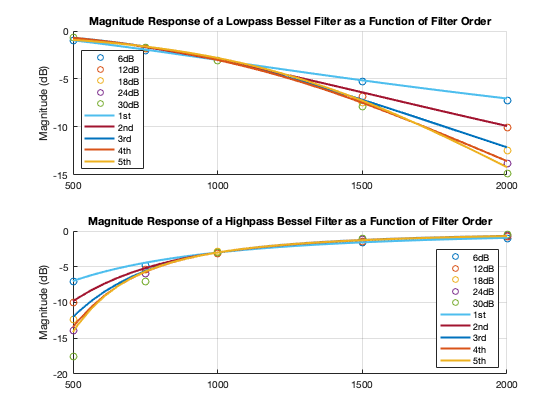

% Here is the measured result 
freq = [500, 750, 1000, 1500, 2000];
y_low = zeros(8, 5);
y_high = zeros(8, 5);
y_low(1,:) = [-1, -2, -3.1, -5.3, -7.2]; % -6dB
y_low(2,:) = [-0.7, -1.8, -3.1, -6.8, -10];% -12dB
y_low(3,:) = [-0.7, -1.7, -3.1, -7.5, -12.4];% -18dB
y_low(4,:) = [-0.7, -1.7, -3.1, -7.9, -13.8];% -24dB
y_low(5,:) = [-0.7, -1.7, -3.1, -7.9, -14.8];% -30dB
y_low(6,:) = [-0.7, -1.7, -3.1, -7.9, -14.8];% -36dB
y_low(7,:) = [-0.7, -1.7, -3.1, -7.8, -14.8];% -42dB
y_low(8,:) = [-0.7, -1.7, -3.1, -7.8, -14.3];% -48dB
y_high(1,:) = [-7.1, -4.8, -3.1, -1.6, -1];% -6dB
y_high(2,:) = [-10, -5.4, -3.1, -1.4, -0.8];% -12dB
y_high(3,:) = [-12.4, -6, -2.9, -1.05, -0.5];% -18dB
y_high(4,:) = [-13.9, -6, -3, -1.2, -0.6];% -24dB
y_high(5,:) = [-17.6, -7, -3, -1, -0.5];% -30dB
y_high(6,:) = [-18.4, -7, -3.5, -1.4, -0.6];% -36dB
y_high(7,:) = [-18.9, -6, -2.8, -1, -0.5];% -42dB
y_high(8,:) = [-19.8, -6.5, -3.1, -1.3, -0.6];% -48dB
%interested range
figure
subplot(2,1,1)
for i =1:1: length(y_low)-3
    sz = 50;
%     c = 1:1:length(freq);
    scatter(freq, y_low(i,:), sz);
    hold on
end
semilogx(w/pi*fs/2, 20*log10(abs(H_low_1)), 'LineWidth', 2);
hold on
semilogx(w/pi*fs/2, 20*log10(abs(H_low_2)), 'LineWidth', 2);
semilogx(w/pi*fs/2, 20*log10(abs(H_low_3)), 'LineWidth', 2);
semilogx(w/pi*fs/2, 20*log10(abs(H_low_4)), 'LineWidth', 2);
semilogx(w/pi*fs/2, 20*log10(abs(H_low_5)), 'LineWidth', 2);
legend({'6dB', '12dB', '18dB', '24dB', '30dB','1st', '2nd', '3rd', '4th', '5th'},'Location','southwest')
ylabel('Magnitude (dB)');
xlim([500 2000])
title('Magnitude Response of a Lowpass Bessel Filter as a Function of Filter Order')
grid on;
subplot(2,1,2)
for i =1:1: length(y_low)-3
    sz = 50;
%     c = linspace(1,1,length(freq));
    scatter(freq, y_high(i,:), sz);
    hold on
end
semilogx(w/pi*fs/2, 20*log10(abs(H_high_1)), 'LineWidth', 2);
hold on
semilogx(w/pi*fs/2, 20*log10(abs(H_high_2)), 'LineWidth', 2);
semilogx(w/pi*fs/2, 20*log10(abs(H_high_3)), 'LineWidth', 2);
semilogx(w/pi*fs/2, 20*log10(abs(H_high_4)), 'LineWidth', 2);
semilogx(w/pi*fs/2, 20*log10(abs(H_high_5)), 'LineWidth', 2)
legend({'6dB', '12dB', '18dB', '24dB', '30dB','1st', '2nd', '3rd', '4th', '5th'},'Location','southeast')
ylabel('Magnitude (dB)');
xlim([500 2000])
title('Magnitude Response of a Highpass Bessel Filter as a Function of Filter Order')
grid on;